imfinfo('puppy.jpg')

ans = struct with fields:
           Filename: 'C:\Users\jayah\Desktop\SC2\HW1\puppy.jpg'
        FileModDate: '20-Feb-2019 03:39:10'
           FileSize: 12675
             Format: 'jpg'
      FormatVersion: ''
              Width: 500
             Height: 448
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Progressive'
            Comment: {}


I = imread('puppy.jpg')

I = 448×500×3 uint8 array
I(:,:,1) =

   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246  

size(I)

ans =    448   500     3


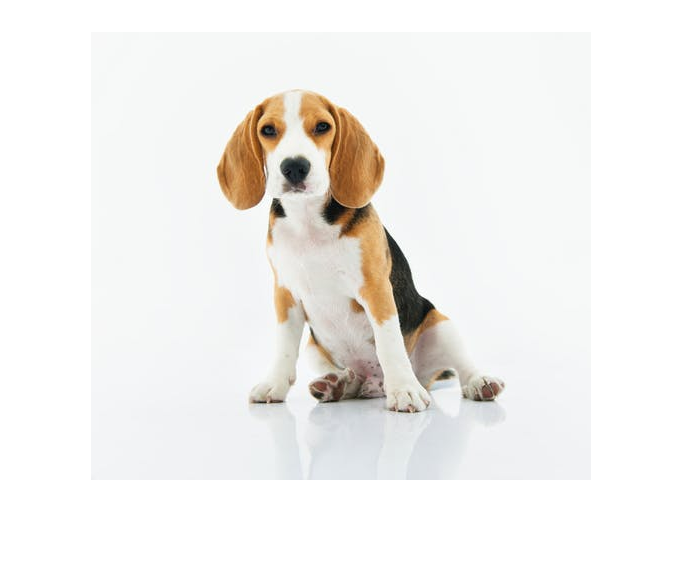

imshow(I)

I2 = rgb2gray(I)

I2 = 448×500 uint8 matrix
   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   248   248
   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   248   248
   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   248   248
   248   248   248   248   248   248   248   248   248   248   248   24

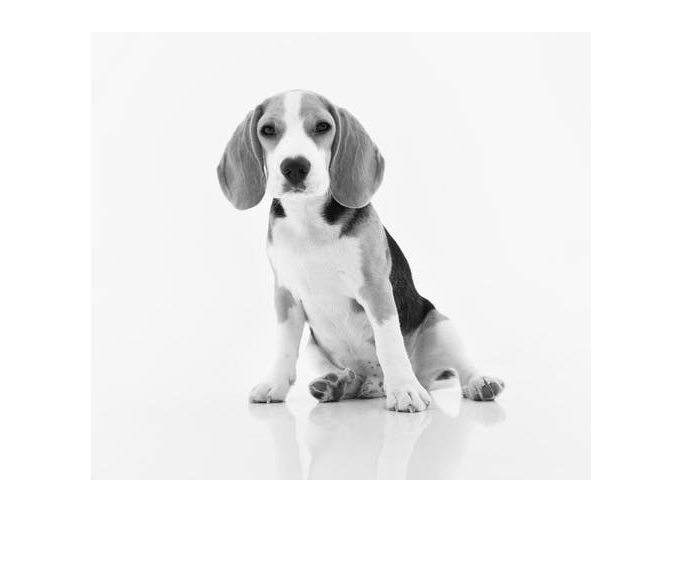

imshow(I2)


imwrite(I2, 'puppy_gray.jpg', 'JPG')
size(I2)

ans =    448   500


I2 = double(I2)

I2 =    248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   248   248
   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   248   248
   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   248   248
   248   248   248   248   248   248   248   248   248   248   248   248   248   248   248  

%pup  = I2 * I2'
I2centered = (I2 - mean(I2))

I2centered =     1.1518    1.1518    1.1451    1.1406    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    1.1518    1.1518    1.1451    1.1406    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

for i= 1:500
    
I2centered(:,i) = I2centered(:,i)/std(I2centered(:,i))  

end

I2centered =     0.7574    1.1518    1.1451    1.1406    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    1.1518    1.1451    1.1406    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    1.1451    1.1406    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    1.1451    1.1406    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    1.1406    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    1.1406    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    1.1339    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    1.1250    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    1.1205    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    1.1183    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.4665    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.4665    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.4665    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.4665    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.4665    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.4665    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.5290    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.5290    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.5290    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.5290    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.5290    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.5290    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.6250    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.6250    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.6250    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.6250    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.6429    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.6429    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.6607    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.6607    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.7143    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.7143    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.7143    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.7143    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.7143    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.7656    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.4957    0.7656    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.4957    0.7656    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.4957    0.4957    0.7656    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.4957    0.4957    0.7656    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.4957    0.4957    0.4957    0.7656    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.4957    0.4957    0.4957    0.7656    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.4957    0.4957    0.4957    0.4957    0.7656    0.7656    1.8683    1.8683
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264    1.1401    1.1401    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4970    0.4957    0.4957    0.4957    0.4957    0.4957    0.4957    0.7656    0.7656    1.

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    

I2centered =     0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.0753    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1037    1.1037    1.1037    1.1037    1.1264    1.1264
    0.7574    0.7618    0.7735    0.7824    0.7921    0.8013    0.8034    0.8031    


pup = (I2centered' * I2centered)/448

pup =     0.9978    0.9968    0.9947    0.9901    0.9812    0.9698    0.9533    0.9423    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.8817    0.8817    0.8817    0.8817    0.8817    0.8817    0.8817    0.8817    0.8828    0.8828    0.8828    0.8828    0.8819    0.8819
    0.9968    0.9978    0.9965    0.9929    0.9859    0.9754    0.9610    0.9510    0.9053    0.9053    0.9053    0.9053    0.9053    0.9053    0.9053    0.9053    0.8868    0.8868    0.8868    0.8868    0.8868    0.8868    0.8868    0.8868    0.8880    0.8880    0.8880    0.8880    0.8871    0.8871
    0.9947    0.9965    0.9978    0.9958    0.9915    0.9837    0.9721    0.9630    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8965    0.8965    0.8965    0.8965    0.8955    0.8955
    0.9901    0.9929    0.9958    0.9978    0.9953    0.9904    0.9807    0.9748    0.9189 

U = []


U =

     []




[X , Y] = eig(pup)

X =     0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   

Y =    -0.9925         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.4276         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   -0.3874         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.3768         0         0         0         0         0   

eigen = eig(pup)

eigen =    -0.9937
   -0.9102
   -0.4219
   -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229


sum(eigen)

ans = 498.8839

max(eigen)

ans = 219.7052

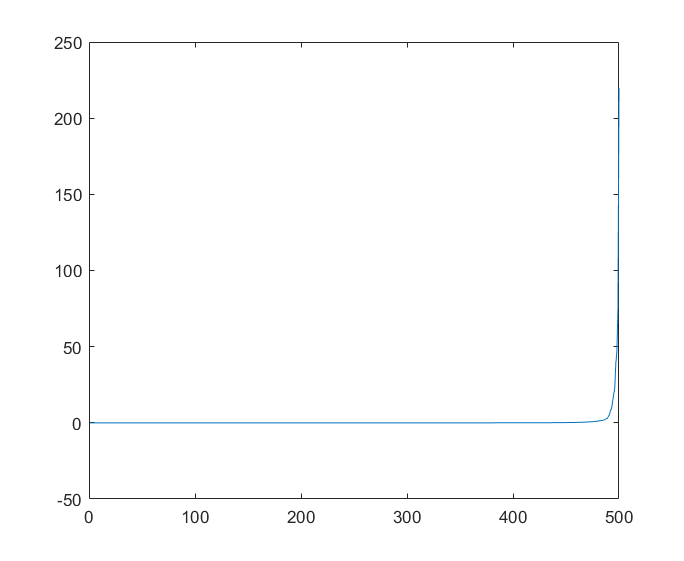

plot(eigen)


p = sum(eigen)

p = 498.8839

a = eigen

a =    -0.9937
   -0.9102
   -0.4219
   -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229



prompt = 'Enter the beta value'

prompt = 'Enter the beta value'

beta = double(input(prompt))

beta = 0.9900

beta = beta

beta = 0.9900

co = 0

co = 0

estimated = 1.00

estimated = 1

while estimated > beta
    [a , estimated] = function23(a, p)
    co = co + 1
    if estimated <= beta
        disp(a)
        break
    end
end

index = 1

a =    -0.9102
   -0.4219
   -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207


newa =    -0.9102
   -0.4219
   -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207


newsum = 498.8839

y = 1

a =    -0.9102
   -0.4219
   -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207


estimated = 1

co = 1

index = 1

a =    -0.4219
   -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178


newa =    -0.4219
   -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178


newsum = 498.8839

y = 1

a =    -0.4219
   -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178


estimated = 1

co = 2

index = 1

a =    -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165


newa =    -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165


newsum = 498.8839

y = 1

a =    -0.3766
   -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165


estimated = 1

co = 3

index = 1

a =    -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165
   -0.0143


newa =    -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165
   -0.0143


newsum = 498.8839

y = 1

a =    -0.2114
   -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165
   -0.0143


estimated = 1

co = 4

index = 1

a =    -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165
   -0.0143
   -0.0139


newa =    -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165
   -0.0143
   -0.0139


newsum = 498.8839

y = 1

a =    -0.1183
   -0.0626
   -0.0411
   -0.0346
   -0.0229
   -0.0207
   -0.0178
   -0.0165
   -0.0143
   -0.0139


estimated = 1

co = 5

index = 1

a =    -0.6256
   -0.4111
   -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200


newa =    -0.6256
   -0.4111
   -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200


newsum = 498.8839

y = 1

a =    -0.6256
   -0.4111
   -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200


estimated = 1

co = 6

index = 1

a =    -0.4111
   -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100


newa =    -0.4111
   -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100


newsum = 498.8839

y = 1

a =    -0.4111
   -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100


estimated = 1

co = 7

index = 1

a =    -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996


newa =    -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996


newsum = 498.8839

y = 1

a =    -0.3463
   -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996


estimated = 1

co = 8

index = 1

a =    -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949


newa =    -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949


newsum = 498.8839

y = 1

a =    -0.2288
   -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949


estimated = 1

co = 9

index = 1

a =    -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904


newa =    -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904


newsum = 498.8839

y = 1

a =    -0.2069
   -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904


estimated = 1

co = 10

index = 1

a =    -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804


newa =    -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804


newsum = 498.8839

y = 1

a =    -0.1776
   -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804


estimated = 1

co = 11

index = 1

a =    -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769


newa =    -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769


newsum = 498.8839

y = 1

a =    -0.1648
   -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769


estimated = 1

co = 12

index = 1

a =    -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736


newa =    -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736


newsum = 498.8839

y = 1

a =    -0.1428
   -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736


estimated = 1

co = 13

index = 1

a =    -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695


newa =    -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695


newsum = 498.8839

y = 1

a =    -0.1391
   -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695


estimated = 1

co = 14

index = 1

a =    -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695
   -0.0664


newa =    -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695
   -0.0664


newsum = 498.8839

y = 1

a =    -0.1200
   -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695
   -0.0664


estimated = 1

co = 15

index = 1

a =    -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695
   -0.0664
   -0.0620


newa =    -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695
   -0.0664
   -0.0620


newsum = 498.8839

y = 1

a =    -0.1100
   -0.0996
   -0.0949
   -0.0904
   -0.0804
   -0.0769
   -0.0736
   -0.0695
   -0.0664
   -0.0620


estimated = 1

co = 16

index = 1

a =    -0.9961
   -0.9491
   -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087


newa =    -0.9961
   -0.9491
   -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087


newsum = 498.8839

y = 1

a =    -0.9961
   -0.9491
   -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087


estimated = 1

co = 17

index = 1

a =    -0.9491
   -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919


newa =    -0.9491
   -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919


newsum = 498.8839

y = 1

a =    -0.9491
   -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919


estimated = 1

co = 18

index = 1

a =    -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686


newa =    -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686


newsum = 498.8839

y = 1

a =    -0.9038
   -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686


estimated = 1

co = 19

index = 1

a =    -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428


newa =    -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428


newsum = 498.8839

y = 1

a =    -0.8044
   -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428


estimated = 1

co = 20

index = 1

a =    -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371


newa =    -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371


newsum = 498.8839

y = 1

a =    -0.7693
   -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371


estimated = 1

co = 21

index = 1

a =    -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186


newa =    -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186


newsum = 498.8839

y = 1

a =    -0.7359
   -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186


estimated = 1

co = 22

index = 1

a =    -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964


newa =    -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964


newsum = 498.8839

y = 1

a =    -0.6949
   -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964


estimated = 1

co = 23

index = 1

a =    -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716


newa =    -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716


newsum = 498.8839

y = 1

a =    -0.6644
   -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716


estimated = 1

co = 24

index = 1

a =    -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518


newa =    -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518


newsum = 498.8839

y = 1

a =    -0.6196
   -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518


estimated = 1

co = 25

index = 1

a =    -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425


newa =    -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425


newsum = 498.8839

y = 1

a =    -0.6087
   -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425


estimated = 1

co = 26

index = 1

a =    -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250


newa =    -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250


newsum = 498.8839

y = 1

a =    -0.5919
   -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250


estimated = 1

co = 27

index = 1

a =    -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249


newa =    -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249


newsum = 498.8839

y = 1

a =    -0.5686
   -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249


estimated = 1

co = 28

index = 1

a =    -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988


newa =    -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988


newsum = 498.8839

y = 1

a =    -0.5428
   -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988


estimated = 1

co = 29

index = 1

a =    -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722


newa =    -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722


newsum = 498.8839

y = 1

a =    -0.5371
   -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722


estimated = 1

co = 30

index = 1

a =    -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621


newa =    -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621


newsum = 498.8839

y = 1

a =    -0.5186
   -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621


estimated = 1

co = 31

index = 1

a =    -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539


newa =    -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539


newsum = 498.8839

y = 1

a =    -0.4964
   -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539


estimated = 1

co = 32

index = 1

a =    -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252


newa =    -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252


newsum = 498.8839

y = 1

a =    -0.4716
   -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252


estimated = 1

co = 33

index = 1

a =    -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158


newa =    -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158


newsum = 498.8839

y = 1

a =    -0.4518
   -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158


estimated = 1

co = 34

index = 1

a =    -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045


newa =    -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045


newsum = 498.8839

y = 1

a =    -0.4425
   -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045


estimated = 1

co = 35

index = 1

a =    -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992


newa =    -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992


newsum = 498.8839

y = 1

a =    -0.4250
   -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992


estimated = 1

co = 36

index = 1

a =    -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929


newa =    -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929


newsum = 498.8839

y = 1

a =    -0.4249
   -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929


estimated = 1

co = 37

index = 1

a =    -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772


newa =    -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772


newsum = 498.8839

y = 1

a =    -0.3988
   -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772


estimated = 1

co = 38

index = 1

a =    -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570


newa =    -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570


newsum = 498.8839

y = 1

a =    -0.3722
   -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570


estimated = 1

co = 39

index = 1

a =    -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502


newa =    -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502


newsum = 498.8839

y = 1

a =    -0.3621
   -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502


estimated = 1

co = 40

index = 1

a =    -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427


newa =    -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427


newsum = 498.8839

y = 1

a =    -0.3539
   -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427


estimated = 1

co = 41

index = 1

a =    -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326


newa =    -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326


newsum = 498.8839

y = 1

a =    -0.3252
   -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326


estimated = 1

co = 42

index = 1

a =    -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270


newa =    -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270


newsum = 498.8839

y = 1

a =    -0.3158
   -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270


estimated = 1

co = 43

index = 1

a =    -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107


newa =    -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107


newsum = 498.8839

y = 1

a =    -0.3045
   -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107


estimated = 1

co = 44

index = 1

a =    -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016


newa =    -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016


newsum = 498.8839

y = 1

a =    -0.2992
   -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016


estimated = 1

co = 45

index = 1

a =    -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934


newa =    -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934


newsum = 498.8839

y = 1

a =    -0.2929
   -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934


estimated = 1

co = 46

index = 1

a =    -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848


newa =    -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848


newsum = 498.8839

y = 1

a =    -0.2772
   -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848


estimated = 1

co = 47

index = 1

a =    -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785


newa =    -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785


newsum = 498.8839

y = 1

a =    -0.2570
   -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785


estimated = 1

co = 48

index = 1

a =    -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629


newa =    -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629


newsum = 498.8839

y = 1

a =    -0.2502
   -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629


estimated = 1

co = 49

index = 1

a =    -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548


newa =    -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548


newsum = 498.8839

y = 1

a =    -0.2427
   -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548


estimated = 1

co = 50

index = 1

a =    -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479


newa =    -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479


newsum = 498.8839

y = 1

a =    -0.2326
   -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479


estimated = 1

co = 51

index = 1

a =    -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431


newa =    -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431


newsum = 498.8839

y = 1

a =    -0.2270
   -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431


estimated = 1

co = 52

index = 1

a =    -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400


newa =    -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400


newsum = 498.8839

y = 1

a =    -0.2107
   -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400


estimated = 1

co = 53

index = 1

a =    -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334


newa =    -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334


newsum = 498.8839

y = 1

a =    -0.2016
   -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334


estimated = 1

co = 54

index = 1

a =    -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308


newa =    -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308


newsum = 498.8839

y = 1

a =    -0.1934
   -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308


estimated = 1

co = 55

index = 1

a =    -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224


newa =    -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224


newsum = 498.8839

y = 1

a =    -0.1848
   -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224


estimated = 1

co = 56

index = 1

a =    -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134


newa =    -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134


newsum = 498.8839

y = 1

a =    -0.1785
   -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134


estimated = 1

co = 57

index = 1

a =    -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091


newa =    -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091


newsum = 498.8839

y = 1

a =    -0.1629
   -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091


estimated = 1

co = 58

index = 1

a =    -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020


newa =    -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020


newsum = 498.8839

y = 1

a =    -0.1548
   -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020


estimated = 1

co = 59

index = 1

a =    -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890


newa =    -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890


newsum = 498.8839

y = 1

a =    -0.1479
   -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890


estimated = 1

co = 60

index = 1

a =    -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864


newa =    -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864


newsum = 498.8839

y = 1

a =    -0.1431
   -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864


estimated = 1

co = 61

index = 1

a =    -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826


newa =    -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826


newsum = 498.8839

y = 1

a =    -0.1400
   -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826


estimated = 1

co = 62

index = 1

a =    -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746


newa =    -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746


newsum = 498.8839

y = 1

a =    -0.1334
   -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746


estimated = 1

co = 63

index = 1

a =    -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678


newa =    -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678


newsum = 498.8839

y = 1

a =    -0.1308
   -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678


estimated = 1

co = 64

index = 1

a =    -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592


newa =    -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592


newsum = 498.8839

y = 1

a =    -0.1224
   -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592


estimated = 1

co = 65

index = 1

a =    -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571


newa =    -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571


newsum = 498.8839

y = 1

a =    -0.1134
   -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571


estimated = 1

co = 66

index = 1

a =    -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571
   -0.0490


newa =    -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571
   -0.0490


newsum = 498.8839

y = 1

a =    -0.1091
   -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571
   -0.0490


estimated = 1

co = 67

index = 1

a =    -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571
   -0.0490
   -0.0435


newa =    -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571
   -0.0490
   -0.0435


newsum = 498.8839

y = 1

a =    -0.1020
   -0.0890
   -0.0864
   -0.0826
   -0.0746
   -0.0678
   -0.0592
   -0.0571
   -0.0490
   -0.0435


estimated = 1

co = 68

index = 1

a =    -0.8899
   -0.8642
   -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541


newa =    -0.8899
   -0.8642
   -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541


newsum = 498.8839

y = 1

a =    -0.8899
   -0.8642
   -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541


estimated = 1

co = 69

index = 1

a =    -0.8642
   -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413


newa =    -0.8642
   -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413


newsum = 498.8839

y = 1

a =    -0.8642
   -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413


estimated = 1

co = 70

index = 1

a =    -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018


newa =    -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018


newsum = 498.8839

y = 1

a =    -0.8258
   -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018


estimated = 1

co = 71

index = 1

a =    -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395


newa =    -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395


newsum = 498.8839

y = 1

a =    -0.7463
   -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395


estimated = 1

co = 72

index = 1

a =    -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031


newa =    -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031


newsum = 498.8839

y = 1

a =    -0.6782
   -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031


estimated = 1

co = 73

index = 1

a =    -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603


newa =    -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603


newsum = 498.8839

y = 1

a =    -0.5919
   -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603


estimated = 1

co = 74

index = 1

a =    -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120


newa =    -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120


newsum = 498.8839

y = 1

a =    -0.5705
   -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120


estimated = 1

co = 75

index = 1

a =    -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231


newa =    -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231


newsum = 498.8839

y = 1

a =    -0.4897
   -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231


estimated = 1

co = 76

index = 1

a =    -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513


newa =    -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513


newsum = 498.8839

y = 1

a =    -0.4352
   -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513


estimated = 1

co = 77

index = 1

a =    -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574


newa =    -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574


newsum = 498.8839

y = 1

a =    -0.3541
   -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574


estimated = 1

co = 78

index = 1

a =    -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191


newa =    -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191


newsum = 498.8839

y = 1

a =    -0.2413
   -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191


estimated = 1

co = 79

index = 1

a =    -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784


newa =    -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784


newsum = 498.8839

y = 1

a =    -0.2018
   -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784


estimated = 1

co = 80

index = 1

a =    -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498


newa =    -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498


newsum = 498.8839

y = 1

a =    -0.1395
   -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498


estimated = 1

co = 81

index = 1

a =    -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380


newa =    -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380


newsum = 498.8839

y = 1

a =    -0.1031
   -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380


estimated = 1

co = 82

index = 1

a =    -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783


newa =    -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783


newsum = 498.8839

y = 1

a =    -0.0603
   -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783


estimated = 1

co = 83

index = 1

a =    -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996


newa =    -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996


newsum = 498.8839

y = 1

a =    -0.0120
    0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996


estimated = 1

co = 84

index = 1

a =     0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398


newa =     0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398


newsum = 498.8839

y = 1

a =     0.0231
    0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398


estimated = 1

co = 85

index = 1

a =     0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266


newa =     0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266


newsum = 498.8839

y = 1

a =     0.0513
    0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266


estimated = 1

co = 86

index = 1

a =     0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235


newa =     0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235


newsum = 498.8839

y = 1

a =     0.1574
    0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235


estimated = 1

co = 87

index = 1

a =     0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235
    0.8681


newa =     0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235
    0.8681


newsum = 498.8839

y = 1

a =     0.2191
    0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235
    0.8681


estimated = 1

co = 88

index = 1

a =     0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235
    0.8681
    0.8751


newa =     0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235
    0.8681
    0.8751


newsum = 498.8839

y = 1

a =     0.2784
    0.3498
    0.4380
    0.4783
    0.5996
    0.6398
    0.7266
    0.8235
    0.8681
    0.8751


estimated = 1

co = 89

index = 1

a =     0.0350
    0.0438
    0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053


newa =     0.0350
    0.0438
    0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053


newsum = 498.8839

y = 1

a =     0.0350
    0.0438
    0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053


estimated = 1

co = 90

index = 1

a =     0.0438
    0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122


newa =     0.0438
    0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122


newsum = 498.8839

y = 1

a =     0.0438
    0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122


estimated = 1

co = 91

index = 1

a =     0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206


newa =     0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206


newsum = 498.8839

y = 1

a =     0.0478
    0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206


estimated = 1

co = 92

index = 1

a =     0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274


newa =     0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274


newsum = 498.8839

y = 1

a =     0.0600
    0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274


estimated = 1

co = 93

index = 1

a =     0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412


newa =     0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412


newsum = 498.8839

y = 1

a =     0.0640
    0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412


estimated = 1

co = 94

index = 1

a =     0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436


newa =     0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436


newsum = 498.8839

y = 1

a =     0.0727
    0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436


estimated = 1

co = 95

index = 1

a =     0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476


newa =     0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476


newsum = 498.8839

y = 1

a =     0.0823
    0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476


estimated = 1

co = 96

index = 1

a =     0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586


newa =     0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586


newsum = 498.8839

y = 1

a =     0.0868
    0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586


estimated = 1

co = 97

index = 1

a =     0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626


newa =     0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626


newsum = 498.8839

y = 1

a =     0.0875
    0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626


estimated = 1

co = 98

index = 1

a =     0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723


newa =     0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723


newsum = 498.8839

y = 1

a =     0.1053
    0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723


estimated = 1

co = 99

index = 1

a =     0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742


newa =     0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742


newsum = 498.8839

y = 1

a =     0.1122
    0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742


estimated = 1

co = 100

index = 1

a =     0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855


newa =     0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855


newsum = 498.8839

y = 1

a =     0.1206
    0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855


estimated = 1

co = 101

index = 1

a =     0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012


newa =     0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012


newsum = 498.8839

y = 1

a =     0.1274
    0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012


estimated = 1

co = 102

index = 1

a =     0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088


newa =     0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088


newsum = 498.8839

y = 1

a =     0.1412
    0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088


estimated = 1

co = 103

index = 1

a =     0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200


newa =     0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200


newsum = 498.8839

y = 1

a =     0.1436
    0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200


estimated = 1

co = 104

index = 1

a =     0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239


newa =     0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239


newsum = 498.8839

y = 1

a =     0.1476
    0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239


estimated = 1

co = 105

index = 1

a =     0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291


newa =     0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291


newsum = 498.8839

y = 1

a =     0.1586
    0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291


estimated = 1

co = 106

index = 1

a =     0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405


newa =     0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405


newsum = 498.8839

y = 1

a =     0.1626
    0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405


estimated = 1

co = 107

index = 1

a =     0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435


newa =     0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435


newsum = 498.8839

y = 1

a =     0.1723
    0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435


estimated = 1

co = 108

index = 1

a =     0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508


newa =     0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508


newsum = 498.8839

y = 1

a =     0.1742
    0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508


estimated = 1

co = 109

index = 1

a =     0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581


newa =     0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581


newsum = 498.8839

y = 1

a =     0.1855
    0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581


estimated = 1

co = 110

index = 1

a =     0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749


newa =     0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749


newsum = 498.8839

y = 1

a =     0.2012
    0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749


estimated = 1

co = 111

index = 1

a =     0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901


newa =     0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901


newsum = 498.8839

y = 1

a =     0.2088
    0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901


estimated = 1

co = 112

index = 1

a =     0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947


newa =     0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947


newsum = 498.8839

y = 1

a =     0.2200
    0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947


estimated = 1

co = 113

index = 1

a =     0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252


newa =     0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252


newsum = 498.8839

y = 1

a =     0.2239
    0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252


estimated = 1

co = 114

index = 1

a =     0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330


newa =     0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330


newsum = 498.8839

y = 1

a =     0.2291
    0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330


estimated = 1

co = 115

index = 1

a =     0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417


newa =     0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417


newsum = 498.8839

y = 1

a =     0.2405
    0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417


estimated = 1

co = 116

index = 1

a =     0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551


newa =     0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551


newsum = 498.8839

y = 1

a =     0.2435
    0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551


estimated = 1

co = 117

index = 1

a =     0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633


newa =     0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633


newsum = 498.8839

y = 1

a =     0.2508
    0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633


estimated = 1

co = 118

index = 1

a =     0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674


newa =     0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674


newsum = 498.8839

y = 1

a =     0.2581
    0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674


estimated = 1

co = 119

index = 1

a =     0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792


newa =     0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792


newsum = 498.8839

y = 1

a =     0.2749
    0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792


estimated = 1

co = 120

index = 1

a =     0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044


newa =     0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044


newsum = 498.8839

y = 1

a =     0.2901
    0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044


estimated = 1

co = 121

index = 1

a =     0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198


newa =     0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198


newsum = 498.8839

y = 1

a =     0.2947
    0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198


estimated = 1

co = 122

index = 1

a =     0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267


newa =     0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267


newsum = 498.8839

y = 1

a =     0.3252
    0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267


estimated = 1

co = 123

index = 1

a =     0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639


newa =     0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639


newsum = 498.8839

y = 1

a =     0.3330
    0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639


estimated = 1

co = 124

index = 1

a =     0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798


newa =     0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798


newsum = 498.8839

y = 1

a =     0.3417
    0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798


estimated = 1

co = 125

index = 1

a =     0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984


newa =     0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984


newsum = 498.8839

y = 1

a =     0.3551
    0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984


estimated = 1

co = 126

index = 1

a =     0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105


newa =     0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105


newsum = 498.8839

y = 1

a =     0.3633
    0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105


estimated = 1

co = 127

index = 1

a =     0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163


newa =     0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163


newsum = 498.8839

y = 1

a =     0.3674
    0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163


estimated = 1

co = 128

index = 1

a =     0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456


newa =     0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456


newsum = 498.8839

y = 1

a =     0.3792
    0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456


estimated = 1

co = 129

index = 1

a =     0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735


newa =     0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735


newsum = 498.8839

y = 1

a =     0.4044
    0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735


estimated = 1

co = 130

index = 1

a =     0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002


newa =     0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002


newsum = 498.8839

y = 1

a =     0.4198
    0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002


estimated = 1

co = 131

index = 1

a =     0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608


newa =     0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608


newsum = 498.8839

y = 1

a =     0.4267
    0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608


estimated = 1

co = 132

index = 1

a =     0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690


newa =     0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690


newsum = 498.8839

y = 1

a =     0.4639
    0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690


estimated = 1

co = 133

index = 1

a =     0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013


newa =     0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013


newsum = 498.8839

y = 1

a =     0.4798
    0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013


estimated = 1

co = 134

index = 1

a =     0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228


newa =     0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228


newsum = 498.8839

y = 1

a =     0.4984
    0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228


estimated = 1

co = 135

index = 1

a =     0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549


newa =     0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549


newsum = 498.8839

y = 1

a =     0.5105
    0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549


estimated = 1

co = 136

index = 1

a =     0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087


newa =     0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087


newsum = 498.8839

y = 1

a =     0.5163
    0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087


estimated = 1

co = 137

index = 1

a =     0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114


newa =     0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114


newsum = 498.8839

y = 1

a =     0.5456
    0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114


estimated = 1

co = 138

index = 1

a =     0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114
    0.8707


newa =     0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114
    0.8707


newsum = 498.8839

y = 1

a =     0.5735
    0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114
    0.8707


estimated = 1

co = 139

index = 1

a =     0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114
    0.8707
    0.9509


newa =     0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114
    0.8707
    0.9509


newsum = 498.8839

y = 1

a =     0.6002
    0.6608
    0.6690
    0.7013
    0.7228
    0.7549
    0.8087
    0.8114
    0.8707
    0.9509


estimated = 1

co = 140

index = 1

a =     0.0661
    0.0669
    0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073


newa =     0.0661
    0.0669
    0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073


newsum = 498.8839

y = 1

a =     0.0661
    0.0669
    0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073


estimated = 1

co = 141

index = 1

a =     0.0669
    0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106


newa =     0.0669
    0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106


newsum = 498.8839

y = 1

a =     0.0669
    0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106


estimated = 1

co = 142

index = 1

a =     0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177


newa =     0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177


newsum = 498.8839

y = 1

a =     0.0701
    0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177


estimated = 1

co = 143

index = 1

a =     0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289


newa =     0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289


newsum = 498.8839

y = 1

a =     0.0723
    0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289


estimated = 1

co = 144

index = 1

a =     0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406


newa =     0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406


newsum = 498.8839

y = 1

a =     0.0755
    0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406


estimated = 1

co = 145

index = 1

a =     0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454


newa =     0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454


newsum = 498.8839

y = 1

a =     0.0809
    0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454


estimated = 1

co = 146

index = 1

a =     0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646


newa =     0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646


newsum = 498.8839

y = 1

a =     0.0811
    0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646


estimated = 1

co = 147

index = 1

a =     0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784


newa =     0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784


newsum = 498.8839

y = 1

a =     0.0871
    0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784


estimated = 1

co = 148

index = 1

a =     0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277


newa =     0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277


newsum = 498.8839

y = 1

a =     0.0951
    0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277


estimated = 1

co = 149

index = 1

a =     0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127


newa =     0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127


newsum = 498.8839

y = 1

a =     0.1073
    0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127


estimated = 1

co = 150

index = 1

a =     0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965


newa =     0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965


newsum = 498.8839

y = 1

a =     0.1106
    0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965


estimated = 1

co = 151

index = 1

a =     0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965
    0.4677


newa =     0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965
    0.4677


newsum = 498.8839

y = 1

a =     0.1177
    0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965
    0.4677


estimated = 1

co = 152

index = 1

a =     0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965
    0.4677
    0.7374


newa =     0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965
    0.4677
    0.7374


newsum = 498.8839

y = 1

a =     0.1289
    0.1406
    0.1454
    0.1646
    0.1784
    0.2277
    0.3127
    0.3965
    0.4677
    0.7374


estimated = 1

co = 153

index = 1

a =     0.0141
    0.0145
    0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120


newa =     0.0141
    0.0145
    0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120


newsum = 498.8839

y = 1

a =     0.0141
    0.0145
    0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120


estimated = 1

co = 154

index = 1

a =     0.0145
    0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710


newa =     0.0145
    0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710


newsum = 498.8839

y = 1

a =     0.0145
    0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710


estimated = 1

co = 155

index = 1

a =     0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748


newa =     0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748


newsum = 498.8839

y = 1

a =     0.0165
    0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748


estimated = 1

co = 156

index = 1

a =     0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748
    0.2368


newa =     0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748
    0.2368


newsum = 498.8839

y = 1

a =     0.0178
    0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748
    0.2368


estimated = 1

co = 157

index = 1

a =     0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748
    0.2368
    0.2499


newa =     0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748
    0.2368
    0.2499


newsum = 498.8839

y = 1

a =     0.0228
    0.0313
    0.0397
    0.0468
    0.0737
    0.1120
    0.1710
    0.1748
    0.2368
    0.2499


estimated = 1

co = 158

index = 1

a =     0.0031
    0.0040
    0.0047
    0.0074
    0.0112
    0.0171
    0.0175
    0.0237
    0.0250
    0.1621


newa =     0.0031
    0.0040
    0.0047
    0.0074
    0.0112
    0.0171
    0.0175
    0.0237
    0.0250
    0.1621


newsum = 498.8839

y = 1

a =     0.0031
    0.0040
    0.0047
    0.0074
    0.0112
    0.0171
    0.0175
    0.0237
    0.0250
    0.1621


estimated = 1

co = 159

index = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178


newa =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178


newsum = 498.8839

y = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178


estimated = 1

co = 160

index = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086


newa =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086


newsum = 498.8839

y = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086


estimated = 1

co = 161

index = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702


newa =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702


newsum = 498.8839

y = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702


estimated = 1

co = 162

index = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552


newa =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552


newsum = 498.8839

y = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552


estimated = 1

co = 163

index = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521


newa =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521


newsum = 498.8839

y = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521


estimated = 1

co = 164

index = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833


newa =     0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833


newsum = 498.8839

y = 1

a =     0.0000
    0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833


estimated = 1

co = 165

index = 1

a =     0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833
    0.7845


newa =     0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833
    0.7845


newsum = 498.8839

y = 1

a =     0.0000
    0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833
    0.7845


estimated = 1

co = 166

index = 1

a =     0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833
    0.7845
    0.9706


newa =     0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833
    0.7845
    0.9706


newsum = 498.8839

y = 1

a =     0.0000
    0.0000
    0.2178
    0.3086
    0.3702
    0.4552
    0.5521
    0.5833
    0.7845
    0.9706


estimated = 1

co = 167

index = 1

a =     0.0000
    0.0218
    0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099


newa =     0.0000
    0.0218
    0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099


newsum = 498.8839

y = 1

a =     0.0000
    0.0218
    0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099


estimated = 1

co = 168

index = 1

a =     0.0218
    0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189


newa =     0.0218
    0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189


newsum = 498.8839

y = 1

a =     0.0218
    0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189


estimated = 1

co = 169

index = 1

a =     0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299


newa =     0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299


newsum = 498.8839

y = 1.0000

a =     0.0309
    0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299


estimated = 1.0000

co = 170

index = 1

a =     0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497


newa =     0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497


newsum = 498.8839

y = 1.0000

a =     0.0370
    0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497


estimated = 1.0000

co = 171

index = 1

a =     0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654


newa =     0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654


newsum = 498.8839

y = 1.0000

a =     0.0455
    0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654


estimated = 1.0000

co = 172

index = 1

a =     0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674


newa =     0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674


newsum = 498.8839

y = 1.0000

a =     0.0552
    0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674


estimated = 1.0000

co = 173

index = 1

a =     0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757


newa =     0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757


newsum = 498.8839

y = 1.0000

a =     0.0583
    0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757


estimated = 1.0000

co = 174

index = 1

a =     0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917


newa =     0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917


newsum = 498.8839

y = 1.0000

a =     0.0784
    0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917


estimated = 1.0000

co = 175

index = 1

a =     0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952


newa =     0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952


newsum = 498.8839

y = 1.0000

a =     0.0971
    0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952


estimated = 1.0000

co = 176

index = 1

a =     0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051


newa =     0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051


newsum = 498.8839

y = 1.0000

a =     0.1099
    0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051


estimated = 1.0000

co = 177

index = 1

a =     0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166


newa =     0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166


newsum = 498.8839

y = 1.0000

a =     0.1189
    0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166


estimated = 1.0000

co = 178

index = 1

a =     0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351


newa =     0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351


newsum = 498.8839

y = 1.0000

a =     0.1299
    0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351


estimated = 1.0000

co = 179

index = 1

a =     0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619


newa =     0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619


newsum = 498.8839

y = 1.0000

a =     0.1497
    0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619


estimated = 1.0000

co = 180

index = 1

a =     0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732


newa =     0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732


newsum = 498.8839

y = 1.0000

a =     0.1654
    0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732


estimated = 1.0000

co = 181

index = 1

a =     0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990


newa =     0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990


newsum = 498.8839

y = 1.0000

a =     0.1674
    0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990


estimated = 1.0000

co = 182

index = 1

a =     0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990
    0.3026


newa =     0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990
    0.3026


newsum = 498.8839

y = 1.0000

a =     0.1757
    0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990
    0.3026


estimated = 1.0000

co = 183

index = 1

a =     0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990
    0.3026
    0.3256


newa =     0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990
    0.3026
    0.3256


newsum = 498.8839

y = 1.0000

a =     0.1917
    0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990
    0.3026
    0.3256


estimated = 1.0000

co = 184

index = 1

a =     0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990
    0.3026
    0.3256
    0.3498


newa =     0.1952
    0.2051
    0.2166
    0.2351
    0.2619
    0.2732
    0.2990
    0.3026
    0.3256
    0.3498


newsum = 498.8839

lena = length(a)
P = zeros(448,500)
for i= 1:lena
    index = find(eigen == a(i))
    U = [I2centered*X(:,index)/sqrt(Y(index,index))]
    p1 = sqrt(Y(index,index))*U*X(:,index)'
    P = P + p1
end
I = mat2gray(P)
imshow(I)
frob = norm(I2-P,'fro')

function [a] = rmvfunction(a,leas)
index = find(a==leas)
a(index) = []
end


function [newa ,y] = function23(a, p)
newa = rmvfunction(a, min(a))
newsum = sum(newa)
y = newsum/p
end
